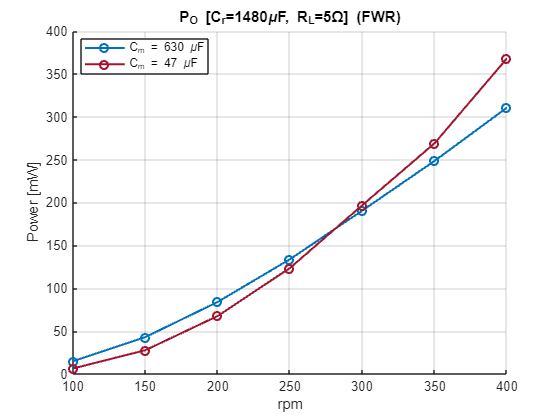


% Dati misurati (D1_f_sweep.csv, D2_f_sweep.csv):
% sweep di rpm per 7 valori fissi del condensatore di compensazione C_m,
% sommati sui due bridge FWR-Delta per ottenere la potenza totale e il rendimento.
% R_L = 7 Ohm fisso (stesso valore riportato in entrambi i CSV).
% NOTA: i CSV originali usano il punto "." come separatore delle migliaia (es. "1.147,796"
% mW); nell'export e' stato sostituito da una virgola, dando un formato a tre gruppi
% "1,147,796" che va decodificato come 1147.796 mW (i gruppi prima dell'ultimo
% costituiscono la parte intera, l'ultimo gruppo sono i millesimi).
% CORREZIONI (valori anomali di un ordine di grandezza rispetto alle celle vicine della
% stessa riga, stesso tipo di errore di virgola gia' visto nel C_sweep/R_sweep):
%   D1, rpm=200, C_m=530uF : Po  49.817  -> 498.17
%   D1, rpm=250, C_m=200uF : Pi 177.323  -> 1773.23
%   D2, rpm=400, C_m=630uF : Po 181.742  -> 1817.42
%
% Per C_m = 630 uF e C_m = 47 uF e' disponibile anche la misura reale con i due bridge
% gia' collegati in parallelo (D_1+2_f_sweep.csv, R_L = 5 Ohm, nessun dato di Pi): queste
% due colonne nel grafico di P_O usano la misura reale al posto della somma calcolata dei
% bridge singoli; le altre 5 colonne (530/430/330/200/100 uF) restano la somma calcolata
% a R_L = 7 Ohm. Il grafico di efficienza resta invariato (calcolato dai bridge singoli),
% perche' il file della misura in parallelo non contiene Pi.

C_r = 1480e-6;      % F - condensatore di filtro/raddrizzatore, fisso
R_L = 7;            % Ohm - carico fisso dei bridge singoli (le due curve "misura reale" sotto sono a R_L=5 Ohm)

rpm_plot = [100 150 200 250 300 350 400];
C_L_plot = [630 530 430 330 200 100 47]*1e-6;   % F
n_CL = numel(C_L_plot);
colors = lines(n_CL);


% Potenza reale misurata con i due bridge gia' in parallelo (D_1+2_f_sweep.csv, R_L=5 Ohm),
% disponibile solo per C_m = 630 uF (colonna 1) e C_m = 47 uF (colonna 7)
Po_meas_630_mW = [148.722 430.397 840.144 1339.088 1906.131 2485.999 3106.791]/10;
Po_meas_47_mW  = [64.545  277.332 676.425 1236.093 1969.002 2691.710 3681.635]/10;

% Grafico P_O ridotto alle sole due colonne con misura reale (bridge gia'
% in parallelo, R_L=5 Ohm): C_m piu' grande (630uF) e C_m piu' piccolo (47uF).
% Le 5 colonne intermedie (somma calcolata dei due bridge singoli) non
% vengono piu' plottate qui.
figure;
hold on;
plot(rpm_plot, P_real_tot(:,1)*1000, 'o-', 'LineWidth', 1.5, 'Color', colors(1,:));
plot(rpm_plot, P_real_tot(:,n_CL)*1000, 'o-', 'LineWidth', 1.5, 'Color', colors(n_CL,:));
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=5\\Omega] (FWR-\\Delta)', C_r*1e6));
xlabel('rpm');
ylabel('Power [mW]');

legendEntries_Po = {sprintf('C_m = %.0f \\muF', C_L_plot(1)*1e6), sprintf('C_m = %.0f \\muF', C_L_plot(n_CL)*1e6)};
legend(legendEntries_Po, 'Location', 'best');
hold off;

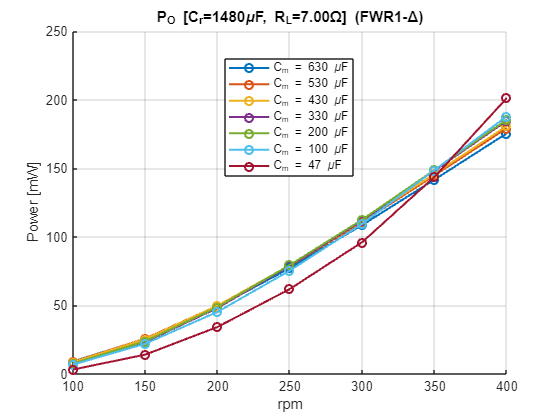




% Sweep di frequenza dei singoli bridge D1/D2 (D1_f_sweep.csv, D2_f_sweep.csv),
% un grafico ciascuno, a confronto con le curve sopra (somma calcolata / misura reale).
% R_L = 7 Ohm fisso per entrambi (stesso valore usato sopra per i bridge singoli).
% Include le stesse correzioni gia' applicate sopra (D1 rpm=200 C_m=530uF,
% D2 rpm=400 C_m=630uF).

P_b1_mW = [ ...
      91.667   88.954   86.351   74.488   75.617   68.668   32.563; ...
     257.219  258.497  254.876  235.105  239.059  220.965  141.412; ...
     489.275  498.170  498.813  481.632  488.176  453.682  343.338; ...
     772.779  787.392  792.395  789.868  795.289  754.696  620.218; ...
    1086.476 1107.738 1115.551 1118.834 1125.849 1095.556  961.865; ...
    1417.903 1448.029 1459.227 1482.964 1488.366 1486.717 1437.692; ...
    1755.127 1792.966 1808.817 1847.460 1854.898 1879.349 2013.089];

P_b2_mW = [ ...
      88.411   86.034   76.381   77.545   47.141   25.357   11.495; ...
     253.774  246.362  237.020  249.545  164.401  109.150   58.653; ...
     489.338  485.651  485.047  512.080  341.601  277.611  163.915; ...
     782.252  782.915  800.438  840.829  487.869  541.473  362.376; ...
    1106.639 1118.877 1144.346 1197.746  730.381  841.800  674.790; ...
    1457.375 1484.129 1514.087 1582.914  991.250 1143.152 1088.243; ...
    1817.420 1851.058 1893.561 1960.729 1227.541 1398.741 1511.813];

P_real_b1_f = P_b1_mW/1000;
P_real_b2_f = P_b2_mW/1000;

figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, P_real_b1_f(:,k)*1000/10, 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=%.2f\\Omega] (FWR1-\\Delta)', C_r*1e6, R_L));
xlabel('rpm');
ylabel('Power [mW]');
legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;

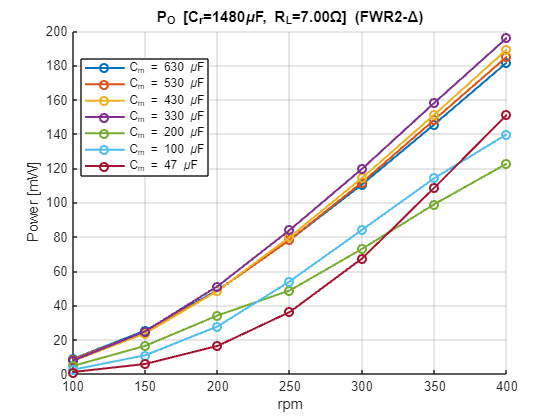


figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, P_real_b2_f(:,k)*1000/10, 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=%.2f\\Omega] (FWR2-\\Delta)', C_r*1e6, R_L));
xlabel('rpm');
ylabel('Power [mW]');
legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;

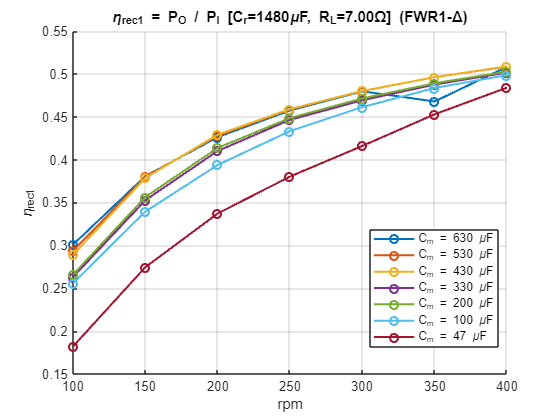



% Efficienza dei singoli bridge D1/D2 (eta_rec = P_O/P_I), stessa disposizione
% righe/colonne di P_b1_mW/P_b2_mW; Pi_b1_mW/Pi_b2_mW letti da D1_f_sweep.csv/
% D2_f_sweep.csv. Include la correzione di virgola gia' segnalata in cima allo
% script (D1, rpm=250, C_m=200uF: Pi 177.323 -> 1773.23); nessun'altra anomalia
% dello stesso tipo e' presente nelle colonne Pi dei due bridge singoli.

Pi_b1_mW = [ ...
     304.663  302.898  298.840  283.238  284.401  268.230  178.836; ...
     675.577  680.334  673.164  666.665  670.889  651.127  515.022; ...
    1147.796 1164.546 1162.493 1174.423 1179.993 1151.993 1018.275; ...
    1689.727 1717.360 1726.369 1769.545 1773.230 1741.705 1630.936; ...
    2265.109 2307.719 2323.381 2384.461 2388.493 2375.051 2312.352; ...
    3030.766 2918.428 2940.870 3041.702 3042.955 3074.789 3174.509; ...
    3453.323 3526.494 3555.464 3682.569 3689.518 3768.670 4159.651];

Pi_b2_mW = [ ...
     309.719  272.898  309.637  298.865  183.264  119.855   73.252; ...
     692.119  612.872  718.478  710.828  467.053  348.248  230.002; ...
    1184.417 1100.776 1263.350 1248.293  836.815  724.381  502.494; ...
    1747.595 1667.383 1919.903 1880.672 1161.082 1250.446  946.912; ...
    2338.443 2305.107 2542.164 2544.383 1608.565 1805.465 1582.390; ...
    2951.968 2981.180 3176.329 3232.677 2048.543 2324.163 2373.436; ...
    3587.512 3637.469 3832.529 3891.444 2423.506 2734.080 3136.848];

eta_b1 = P_b1_mW ./ Pi_b1_mW;
eta_b2 = P_b2_mW ./ Pi_b2_mW;

figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, eta_b1(:,k), 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('\\eta_{rec1} = P_O / P_I [C_r=%.0f\\muF, R_L=%.2f\\Omega] (FWR1-\\Delta)', C_r*1e6, R_L));
xlabel('rpm');
ylabel('\eta_{rec1}');
legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;

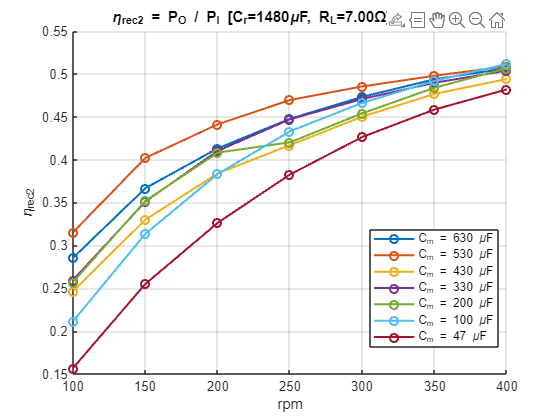


figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, eta_b2(:,k), 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('\\eta_{rec2} = P_O / P_I [C_r=%.0f\\muF, R_L=%.2f\\Omega] (FWR2-\\Delta)', C_r*1e6, R_L));
xlabel('rpm');
ylabel('\eta_{rec2}');
legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;